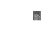

%Read a low-contrast grayscale image into the workspace and display it.

I = imread('pout.tif');
imshow(I)

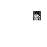

%Adjust the contrast of the image so that 1% of the data is saturated at low and high intensities, and display it.

J = imadjust(I);
figure
imshow(J)

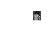

%Adjust the contrast of the image, specifying contrast limits.

K = imadjust(I,[0.3 0.7],[]);
figure
imshow(K)

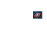

%Read an RGB image into the workspace and display it.

RGB = imread('football.jpg');
imshow(RGB)

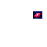

%Adjust the contrast of the RGB image, specifying contrast limits.

RGB2 = imadjust(RGB,[.2 .3 0; .6 .7 1],[]);
figure
imshow(RGB2)

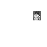

%Calculate the standard deviation and the image mean for stretching.
n = 2;  
Idouble = im2double(I);
avg = mean2(Idouble);
sigma = std2(Idouble);
%Adjust the contrast based on the standard deviation.
J2 = imadjust(I,[avg-n*sigma avg+n*sigma],[]);
%Display the adjusted image.
imshow(J2)

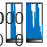

figure
subplot(1,2,1)
imhist(I)
title("Histogram of pout 1.tif")
subplot(1,2,2)
imhist(J)
title("Histogram of pout 2.tif");

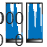

figure
subplot(1,2,1)
imhist(K)
title("Histogram of pout 3.tif")
subplot(1,2,2)
imhist(J2)
title("Histogram of pout 4.tif");

[height, width, numChannels] = size(I);
fprintf('Số pixel của ảnh: %d\n', height * width * numChannels);

Số pixel của ảnh: 69840
